## Visualization of Prediction Results

Creation of plots to visualize the results of the prediction analyses (bar graphs and matrices) 

- Run all scripts in HCP Data Prep and Scripts for HCP - Main Sample 

**1. Visualization of results of the prediction analyses of the internally cross-validated Basic and Expanded NMA models in a matrix**

1.1. Retrieve the results from the predictive analyses

matrix = [-.0116, -.0267, .0691, -.0129, .0552;
          .0067, .0293, .0317, -.0605, .0004;
          -.0422, .0462, .1029, -.0300, .0452;
          .0281, .0804, .0708, .0648, .0416;
          -.0148, .0185, .0792, -.0266, .0313;
          .0375, -.0779, .0829, .0133, .0253;
          .0802, .0676, .0744, -.0607, .0847;
          .0633, .0522, .0936, .0631, .0318;
          .0419, .0632, .1362, .0185, .0636]

matrix =    -0.0116   -0.0267    0.0691   -0.0129    0.0552
    0.0067    0.0293    0.0317   -0.0605    0.0004
   -0.0422    0.0462    0.1029   -0.0300    0.0452
    0.0281    0.0804    0.0708    0.0648    0.0416
   -0.0148    0.0185    0.0792   -0.0266    0.0313
    0.0375   -0.0779    0.0829    0.0133    0.0253
    0.0802    0.0676    0.0744   -0.0607    0.0847
    0.0633    0.0522    0.0936    0.0631    0.0318
    0.0419    0.0632    0.1362    0.0185    0.0636


1.2. Create Colormap

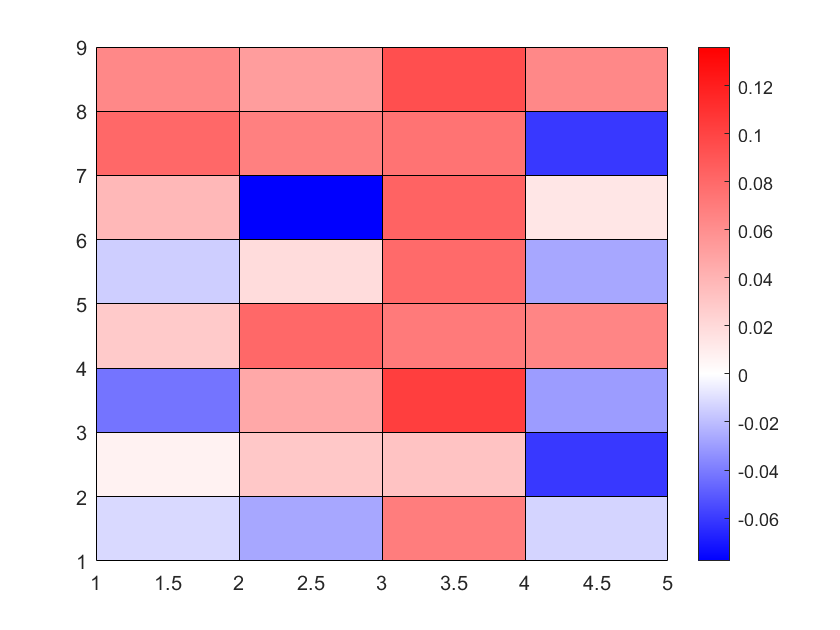

L = 45;             %number of datapoints
data = matrix; % input data 

indexValue = 0;     % value for which to set a particular color
topColor = [1 0 0];         % color for maximum data value (red = [1 0 0])
indexColor = [1 1 1];       % color for indexed data value (white = [1 1 1])
bottomcolor = [0 0 1];      % color for minimum data value (blue = [0 0 1])

% Calculate where proportionally indexValue lies between minimum and
% maximum values

largest = max(max(data));
smallest = min(min(data));
index = L*abs(indexValue-smallest)/(largest-smallest);

% Create color map ranging from bottom color to index color
% Multipling number of points by 100 adds more resolution
customCMap1 = [linspace(bottomcolor(1),indexColor(1),100*index)',...
            linspace(bottomcolor(2),indexColor(2),100*index)',...
            linspace(bottomcolor(3),indexColor(3),100*index)'];

% Create color map ranging from index color to top color
% Multipling number of points by 100 adds more resolution
customCMap2 = [linspace(indexColor(1),topColor(1),100*(L-index))',...
            linspace(indexColor(2),topColor(2),100*(L-index))',...
            linspace(indexColor(3),topColor(3),100*(L-index))'];
customCMap = [customCMap1;customCMap2];  % Combine colormaps
colormap(customCMap)
psudo = pcolor(data);
colorbar

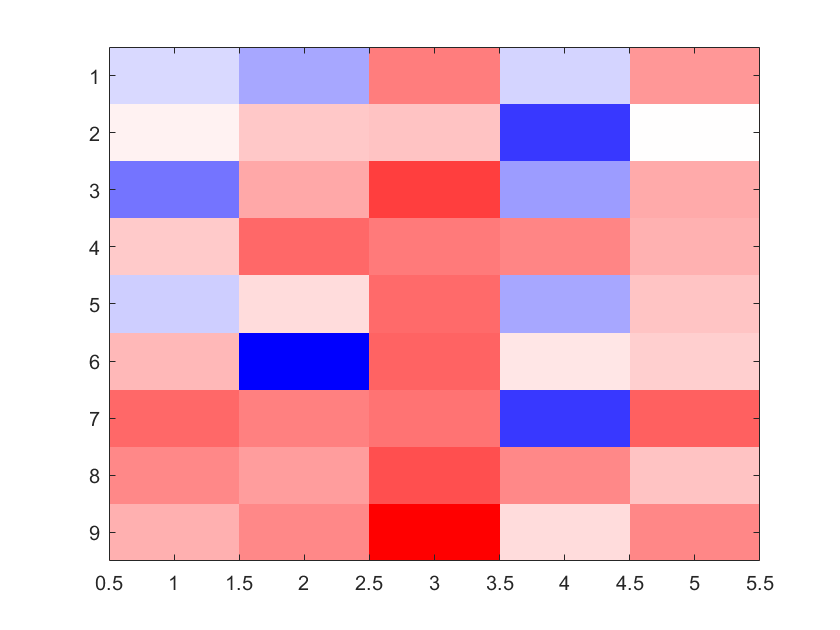

imagesc(data)
colormap(customCMap)

**2. Create the bar plots to compare the prediction performances**

2.1. Comparison of condition-specific predictions (intelligence and personality) 

matrix_all = [.1769,-.0116, -.0264, .0691, -.0129, .0552;
          .1224, .0067, .0293, .0317, -.0605, .0004;
         .1847, -.0422, .0462, .1029, -.0300, .0452;
          .1489, .0281, .0804, .0708, .0648, .0416;
          .0680, -.0148, .0185, .0792, -.0266, .0313;
          .1218, .0375, -.0779, .0829, .0133, .0253;
          .2196, .0802, .0676, .0744, -.0607, .0847;
          .2544, .0633, .0522, .0936, .0631, .0318;
          .2682, .0419, .0632, .1362, .0185, .0636]

matrix_all =     0.1769   -0.0116   -0.0264    0.0691   -0.0129    0.0552
    0.1224    0.0067    0.0293    0.0317   -0.0605    0.0004
    0.1847   -0.0422    0.0462    0.1029   -0.0300    0.0452
    0.1489    0.0281    0.0804    0.0708    0.0648    0.0416
    0.0680   -0.0148    0.0185    0.0792   -0.0266    0.0313
    0.1218    0.0375   -0.0779    0.0829    0.0133    0.0253
    0.2196    0.0802    0.0676    0.0744   -0.0607    0.0847
    0.2544    0.0633    0.0522    0.0936    0.0631    0.0318
    0.2682    0.0419    0.0632    0.1362    0.0185    0.0636


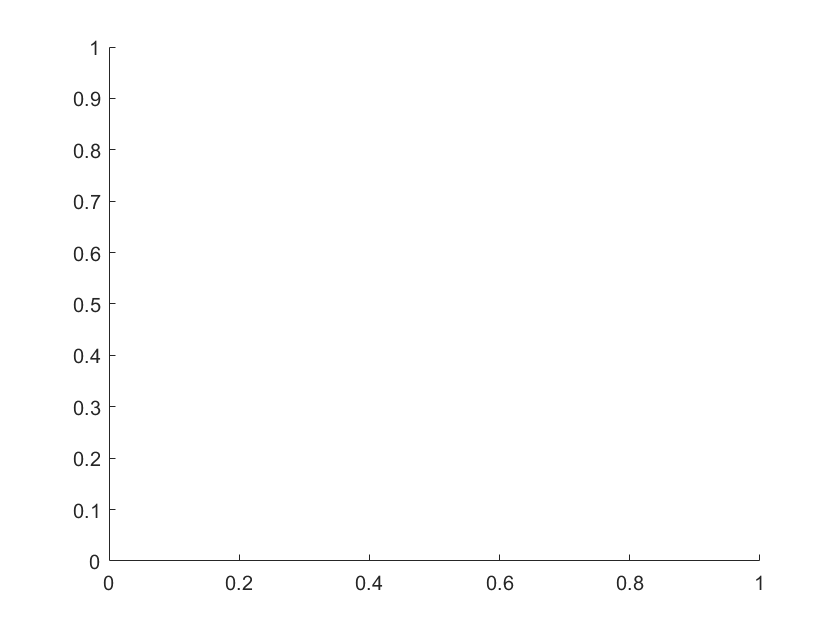

Error using matlab.graphics.chart.primitive.Bar
Unrecognized property GroupWidth for class Bar.

Error in bar (line 241)
        h(i) = matlab.graphics.chart.primitive.Bar('Parent',hPar,...

% barplot = bar(matrix_all,'GroupWidth',0.7)

Load all relevant data files

Personality prediction

folder = 'C:\Users\jop86ib\Desktop\Test Model Difference Paper 3\Model Difference Test - Main Sample\Basic NMA Model for Figures';
files = dir(fullfile(folder, '*.mat'));

for i = 1:length(files)
    % Get filename without extension
    [~, name, ~] = fileparts(files(i).name);
    filePath = fullfile(folder, files(i).name);
    
    % Load the file into a struct
    temp = load(filePath);
    
    % If it contains only one variable, extract that variable directly
    if length(fieldnames(temp)) == 1
        % Get the field name
        varname = fieldnames(temp);
        % Extract the content
        data = temp.(varname{1});
        % Assign it in base workspace with the filename as variable name
        assignin('base', name, data);
        fprintf('Loaded: %s as variable of size %s\n', name, mat2str(size(data)));
    else
        warning('File %s contains more than one variable. Skipping.', name);
    end
end

Intelligence prediction

folder = 'C:\Users\jop86ib\Desktop\Test Model Difference Paper 2\Internal Cross-Validation Main Sample\Basic NMA Model for Figures';
files = dir(fullfile(folder, '*.mat'));

for i = 1:length(files)
    % Get filename without extension
    [~, name, ~] = fileparts(files(i).name);
    filePath = fullfile(folder, files(i).name);
    
    % Load the file into a struct
    temp = load(filePath);
    
    % If it contains only one variable, extract that variable directly
    if length(fieldnames(temp)) == 1
        % Get the field name
        varname = fieldnames(temp);
        % Extract the content
        data = temp.(varname{1});
        % Assign it in base workspace with the filename as variable name
        assignin('base', name, data);
        fprintf('Loaded: %s as variable of size %s\n', name, mat2str(size(data)));
    else
        warning('File %s contains more than one variable. Skipping.', name);
    end
end

Create the plot

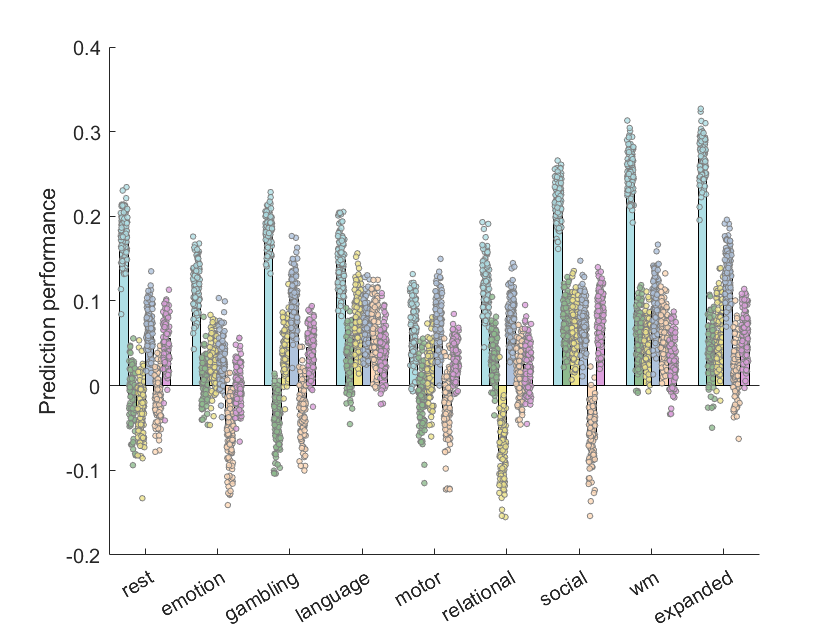

% Define Traits and Tasks
traits = {'G', 'A', 'O', 'C', 'N', 'E'};
tasks = {'rest', 'emotion', 'gambling', 'language', 'motor', ...
         'relational', 'social', 'wm', 'expanded'};
n_traits = numel(traits);
n_tasks = numel(tasks);

% Colors per Trait
colors = [
    rgb('PowderBlue');   % G
    rgb('DarkSeaGreen');   % A
    rgb('Khaki');   % O 
    rgb('LightSteelBlue');   % C 
    rgb('PeachPuff');   % N
    rgb('Plum')    % E 
];

% Load in Data
all_data = cell(n_tasks, n_traits); % [tasks x traits]

for i = 1:n_tasks
    for j = 1:n_traits
        varname = sprintf('All_rhos_final_correlations_%s_%s', tasks{i}, traits{j});
        all_data{i,j} = eval(varname);
    end
end

% Compute Means
mean_data = cellfun(@mean, all_data); % [tasks x traits]

% Prep Barplot
figure; hold on;
groupwidth = 0.7;
bar_width = groupwidth / n_traits;

% X-Position Groups
x = 1:n_tasks;

% Plot each Trait within each Task Group
for j = 1:n_traits
    % X-Position per bar within Group 
    x_shifted = x - groupwidth/2 + (j-0.5)*bar_width;
    % Draw Bars
    bar(x_shifted, mean_data(:,j), bar_width, ...
        'FaceColor', colors(j,:), ...
        'EdgeColor', 'k', ...
        'DisplayName', traits{j});
    
    % Distributions (scatter dots)
    for i = 1:n_tasks
        jitter = (rand(size(all_data{i,j})) - 0.5) * bar_width * 0.8;
        scatter(ones(size(all_data{i,j})) * x_shifted(i) + jitter, all_data{i,j}, ...
            8, 'MarkerFaceColor', colors(j,:), 'MarkerEdgeColor', rgb('Gray'), ...
            'MarkerFaceAlpha', 0.8);
    end
end

% Achses and labels
xticks(x);
xticklabels(tasks);
xtickangle(30);
ylabel('Prediction performance');
% legend(traits, 'Location', 'northeastoutside');
xlim([0.5, n_tasks + 0.5]);
box off;

% title('Prediction performance by Task and Trait');

2.2. Comparison of personality predictions from rest vs. task-combined personality predictions 


data_rest_task_combined = [-.0116,.0419;
                           -.0264,.0632;
                           .0691,.1362;
                           -.0129, .0185;
                           .0552,.0636]




barplot = bar(data_rest_task_combined,'GroupWidth',0.6)

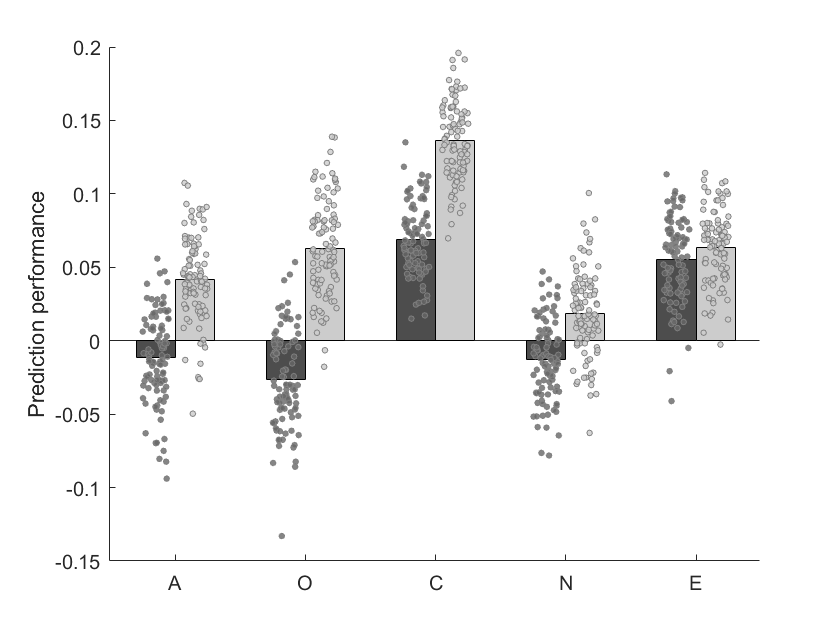

% Name and order of traits
traits = {'A', 'O', 'C', 'N', 'E'};
n_traits = length(traits);

% Prep Data (in desired order)
expanded_data = {
    All_rhos_final_correlations_expanded_A, ...
    All_rhos_final_correlations_expanded_O, ...
    All_rhos_final_correlations_expanded_C, ...
    All_rhos_final_correlations_expanded_N, ...
    All_rhos_final_correlations_expanded_E
};

rest_data = {
    All_rhos_final_correlations_rest_A, ...
    All_rhos_final_correlations_rest_O, ...
    All_rhos_final_correlations_rest_C, ...
    All_rhos_final_correlations_rest_N, ...
    All_rhos_final_correlations_rest_E
};

% Compute means
means_expanded = cellfun(@mean, expanded_data);
means_rest = cellfun(@mean, rest_data);

% Prep Barplot
figure;
hold on;
bar_width = 0.3;
x = 1:n_traits;

% grouped barplot Rest left, Expanded right
bar(x - 0.15, means_rest, bar_width, 'FaceColor', [0.3 0.3 0.3], 'DisplayName', 'Rest');
bar(x + 0.15, means_expanded, bar_width, 'FaceColor', [0.8 0.8 0.8], 'DisplayName', 'Expanded');

% Distributions (scatter / jitter)
for i = 1:n_traits
    jitter_rest = (rand(size(rest_data{i})) - 0.5) * 0.2;
    jitter_tir = (rand(size(expanded_data{i})) - 0.5) * 0.2;
    
    % Rest dots (left)
    scatter(ones(size(rest_data{i})) * (x(i) - 0.15) + jitter_rest, rest_data{i}, ...
        8, 'MarkerEdgeColor', rgb('Gray'), 'MarkerFaceColor', [0.4 0.4 0.4], 'MarkerFaceAlpha', 0.8);
    
    % Expanded dots (right)
    scatter(ones(size(expanded_data{i})) * (x(i) + 0.15) + jitter_tir, expanded_data{i}, ...
        8, 'MarkerEdgeColor', rgb('Gray'), 'MarkerFaceColor', [0.8 0.8 0.8], 'MarkerFaceAlpha', 0.8);
end

% Achses and Labels
xticks(x);
xticklabels(traits);
ylabel('Prediction performance');
% title('Prediction performance across Big Five traits');
% legend('Rest', 'Expanded', 'Location', 'best');
grid off;
xlim([0.5, n_traits + 0.5]);

hold off;

2.3. Comparison of personality predictions from trait-relevant vs. trait-irrelevant region-specific SC-FC Coupling 

data_trait_relevance = [.0569,.0158;
                        .0610, .0706;
                        .1029, .0795;
                        -.0300, -.0042
                        .0887, .0184]
barplot = bar(data_trait_relevance,'GroupWidth',0.6)

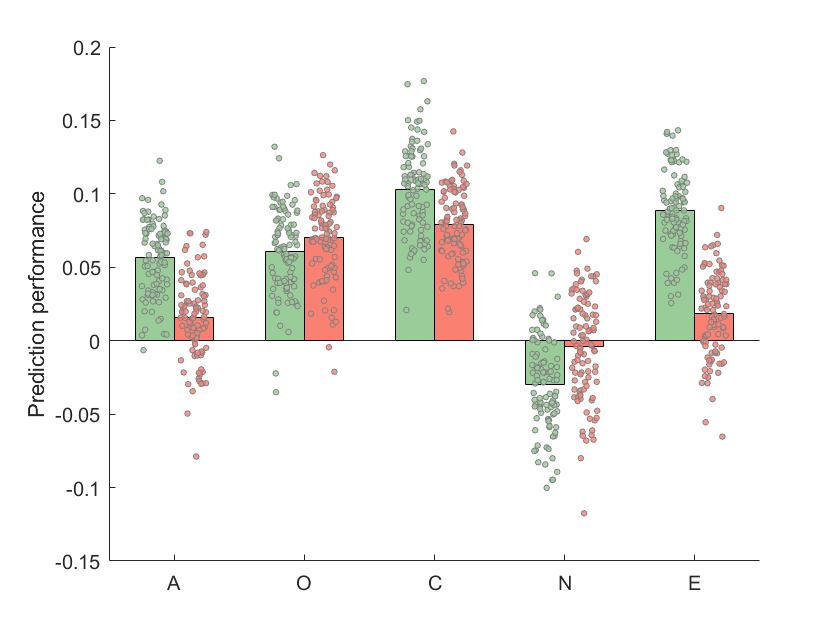

% Name and order of traits
traits = {'A', 'O', 'C', 'N', 'E'};
n_traits = length(traits);

% Prep Data (in desired order)
tr_data = {
    all_rhos_final_correlations_tr_A, ...
    all_rhos_final_correlations_tr_O, ...
    all_rhos_final_correlations_tr_C, ...
    all_rhos_final_correlations_tr_N, ...
    all_rhos_final_correlations_tr_E
};

tir_data = {
    all_rhos_final_correlations_tir_A, ...
    all_rhos_final_correlations_tir_O, ...
    all_rhos_final_correlations_tir_C, ...
    all_rhos_final_correlations_tir_N, ...
    all_rhos_final_correlations_tir_E
};

% Compute means
means_tr = cellfun(@mean, tr_data);
means_tir = cellfun(@mean, tir_data);

% Prep Barplot
figure;
hold on;
bar_width = 0.3;
x = 1:n_traits;

% grouped barplot Rest left, Expanded right
bar(x - 0.15, means_tr, bar_width, 'FaceColor', [0.6, 0.8, 0.6], 'DisplayName', 'TR');
bar(x + 0.15, means_tir, bar_width, 'FaceColor', rgb('Salmon'), 'DisplayName', 'TIR');

% Distributions (scatter / jitter)
for i = 1:n_traits
    jitter_tr = (rand(size(tr_data{i})) - 0.5) * 0.2;
    jitter_tir = (rand(size(tir_data{i})) - 0.5) * 0.2;
    
    % TR dots (left)
    scatter(ones(size(tr_data{i})) * (x(i) - 0.15) + jitter_tr, tr_data{i}, ...
        8, 'MarkerEdgeColor', rgb('Gray')', 'MarkerFaceColor', [0.6, 0.8, 0.6], 'MarkerFaceAlpha', 0.8);
    
    % TIR dots (right)
    scatter(ones(size(tir_data{i})) * (x(i) + 0.15) + jitter_tir, tir_data{i}, ...
        8, 'MarkerEdgeColor', rgb('Gray'), 'MarkerFaceColor', rgb('Salmon'), 'MarkerFaceAlpha', 0.8);
end

% Achses and Labels
xticks(x);
xticklabels(traits);
ylabel('Prediction performance');
% title('Prediction performance across Big Five traits');
% legend('TR', 'TIR', 'Location', 'best');
grid off;
xlim([0.5, n_traits + 0.5]);

hold off;